% Initialisierung der Zustandsvariablen
R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)

% Zeitbereich auf eine Minute erweitern
t = linspace(0, 120, 240);

% Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))];

% Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
V = cumtrapz(t/12, A, 2) + V_0;

% Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Anzahl der Zeitschritte
N = length(t);

% Radarpositionen
pos_radar1 = [0, -10, 0];
pos_radar2 = [-50, 30, 0];
%x_k = [R_0; V_0];
% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_pos(1,:); R_pos(2,:); R_pos(3,:); R_pos(1,:); R_pos(2,:); R_pos(3,:)];





% Prozessrauschkovarianzmatrix Q        (Annahme: Prozessrauschen ist 0, da wir noch keine weiteren Informationen haben)
Q = eye(6) * 0.001;

% Messrauschkovarianzmatrix R (Annahme: gleiche Varianzen für alle Beobachtungen)
standardabweichung = 0.1;
R = (standardabweichung^2) * eye(6);

% Zustandsübergangsmatrix F (Identity matrix as we assume constant velocity)
% Zeitschrittgröße
dt = t(2) - t(1);

% Zustandsübergangsmatrix F
F = [1 0 dt     0 dt 0;
     0 1  0    dt dt 0;
     0 0  1    0  0 0;
     0 0  0    1  0 0;
     0 0  0    0  1 dt;
     0 0  0    0  0 1]; 

% F = [eye(3), eye(3) * dt;
%      zeros(3), eye(3)];

% Schätzung der Anfangsvarianz des Zustandsvektors (Annahme: großer Wert, da wir wenig über den Anfangszustand wissen)
P = 1000 * eye(6);

messungen = [];
% EKF-Schätzung

for k = 2:N
    % Vorhersage
    x_k_pred = F * x_k(:, k-1);
    P_pred = F * P * F' + Q;
    % Update (Kalman Gain)
    H = create_observation_matrix(x_k_pred, pos_radar1, pos_radar2);
    K = P_pred * H' * inv(H * P_pred * H' + R);
    
    % Messungen
    z_k = [calculate_observations(x_k(:, k), pos_radar1); calculate_observations(x_k(:, k), pos_radar2)];
    
    messungen = [messungen, z_k];
    % Update der Zustandsschätzung und Fehlerkovarianz
    x_k(:, k) = x_k_pred + K * (z_k - [calculate_observations(x_k_pred, pos_radar1); calculate_observations(x_k_pred, pos_radar2)]);
    P = (eye(6) - K * H) * P_pred;
end

% Geschätzte Position des Helikopters
estimated_position = x_k(1:3, :)

estimated_position =          0    0.6504   -4.2912    4.4177   -0.9854    1.3020    0.1953    0.6393    0.7096    1.0642    1.4626    1.9170    2.3614    2.7681    3.1257    3.4420    3.7323    4.0119    4.2918    4.5777    4.8714    5.1719    5.4773    5.7860    6.0962    6.4071    6.7179    7.0282    7.3376    7.6456    7.9517    8.2552    8.5554    8.8514    9.1423    9.4269    9.7043    9.9732   10.2324   10.4806   10.7163   10.9381   11.1445   11.3338   11.5046   11.6550   11.7834   11.8881   11.9674   12.0197
         0    0.0001    0.7939    2.0580    2.5229    0.4655    0.3252    0.1104    0.3368    0.6588    1.0387    1.3754    1.6330    1.8000    1.8902    1.9267    1.9334    1.9287    1.9249    1.9290    1.9438    1.9706    2.0095    2.0611    2.1259    2.2051    2.2998    2.4110    2.5396    2.6865    2.8520    3.0366    3.2404    3.4632    3.7049    3.9653    4.2439    4.5403    4.8540    5.1844    5.5308    5.8925    6.2687    6.6585    7.0610    7.4751    7.8999    8.33

% Funktion zur Berechnung der Beobachtungen (Messmodell)

messungen    

messungen =    10.0001   10.0010   10.0037   10.0091   10.0185   10.0332   10.0546   10.0843   10.1238   10.1748   10.2388   10.3173   10.4118   10.5236   10.6540   10.8038   10.9740   11.1650   11.3771   11.6105   11.8649   12.1400   12.4352   12.7496   13.0824   13.4324   13.7985   14.1793   14.5734   14.9796   15.3962   15.8220   16.2553   16.6949   17.1393   17.5870   18.0369   18.4875   18.9377   19.3863   19.8321   20.2742   20.7116   21.1434   21.5687   21.9869   22.3972   22.7991   23.1921   23.5758
   89.9348   89.7396   89.4150   88.9625   88.3845   87.6839   86.8650   85.9332   84.8952   83.7589   82.5336   81.2301   79.8600   78.4362   76.9723   75.4823   73.9805   72.4807   70.9964   69.5402   68.1236   66.7569   65.4487   64.2066   63.0365   61.9429   60.9293   59.9977   59.1494   58.3848   57.7033   57.1043   56.5861   56.1472   55.7857   55.4994   55.2862   55.1439   55.0704   55.0634   55.1210   55.2412   55.4221   55.6620   55.9592   56.3123   56.7197   57.1803   57.6

x_k_new_arr = [];
for i=1:length(messungen(1,:))
    x_k_new1 = x_k(1,i) - pos_radar1(1);
    x_k_new2 = x_k(1,i) - pos_radar1(2);
    x_k_new3 = x_k(1,i) - pos_radar1(3);
    x_k_new4 = x_k(1,i) - pos_radar2(1);
    x_k_new5 = x_k(1,i) - pos_radar2(2);
    x_k_new6 = x_k(1,i) - pos_radar2(3);
    x_k_new_arr = [x_k_new_arr; x_k_new1,x_k_new2,x_k_new3, x_k_new4,x_k_new5,x_k_new6];

end
transpose(x_k_new_arr)

ans =          0    0.6504   -4.2912    4.4177   -0.9854    1.3020    0.1953    0.6393    0.7096    1.0642    1.4626    1.9170    2.3614    2.7681    3.1257    3.4420    3.7323    4.0119    4.2918    4.5777    4.8714    5.1719    5.4773    5.7860    6.0962    6.4071    6.7179    7.0282    7.3376    7.6456    7.9517    8.2552    8.5554    8.8514    9.1423    9.4269    9.7043    9.9732   10.2324   10.4806   10.7163   10.9381   11.1445   11.3338   11.5046   11.6550   11.7834   11.8881   11.9674   12.0197
   10.0000   10.6504    5.7088   14.4177    9.0146   11.3020   10.1953   10.6393   10.7096   11.0642   11.4626   11.9170   12.3614   12.7681   13.1257   13.4420   13.7323   14.0119   14.2918   14.5777   14.8714   15.1719   15.4773   15.7860   16.0962   16.4071   16.7179   17.0282   17.3376   17.6456   17.9517   18.2552   18.5554   18.8514   19.1423   19.4269   19.7043   19.9732   20.2324   20.4806   20.7163   20.9381   21.1445   21.3338   21.5046   21.6550   21.7834   21.8881   21.9674   

messungen_kartesisch = get_kartesische_Koordianten(messungen)

kartesische_koordinaten =     0.0114   10.0001    0.0006   50.0114  -29.9999    0.0006
    0.0455   10.0009    0.0023   50.0455  -29.9991    0.0023
    0.1021   10.0031    0.0051   50.1021  -29.9969    0.0051
    0.1812   10.0074    0.0091   50.1812  -29.9926    0.0091
    0.2824   10.0145    0.0142   50.2824  -29.9855    0.0142
    0.4055   10.0249    0.0205   50.4055  -29.9751    0.0205
    0.5499   10.0395    0.0279   50.5499  -29.9605    0.0279
    0.7152   10.0589    0.0364   50.7152  -29.9411    0.0364
    0.9008   10.0836    0.0461   50.9008  -29.9164    0.0461
    1.1061   10.1143    0.0569   51.1061  -29.8857    0.0569


messungen_kartesisch =     0.0114    0.0455    0.1021    0.1812    0.2824    0.4055    0.5499    0.7152    0.9008    1.1061    1.3304    1.5730    1.8330    2.1094    2.4015    2.7080    3.0281    3.3605    3.7041    4.0577    4.4199    4.7896    5.1654    5.5459    5.9297    6.3154    6.7015    7.0866    7.4692    7.8479    8.2211    8.5873    8.9450    9.2929    9.6293    9.9528   10.2620   10.5555   10.8318   11.0897   11.3277   11.5446   11.7392   11.9102   12.0566   12.1771   12.2708   12.3366   12.3737   12.3812
   10.0001   10.0009   10.0031   10.0074   10.0145   10.0249   10.0395   10.0589   10.0836   10.1143   10.1517   10.1963   10.2487   10.3094   10.3790   10.4579   10.5466   10.6456   10.7553   10.8760   11.0080   11.1518   11.3076   11.4756   11.6560   11.8490   12.0547   12.2732   12.5047   12.7490   13.0061   13.2761   13.5587   13.8539   14.1614   14.4811   14.8126   15.1557   15.5099   15.8751   16.2506   16.6361   17.0310   17.4349   17.8472   18.2672   18.6945   19.

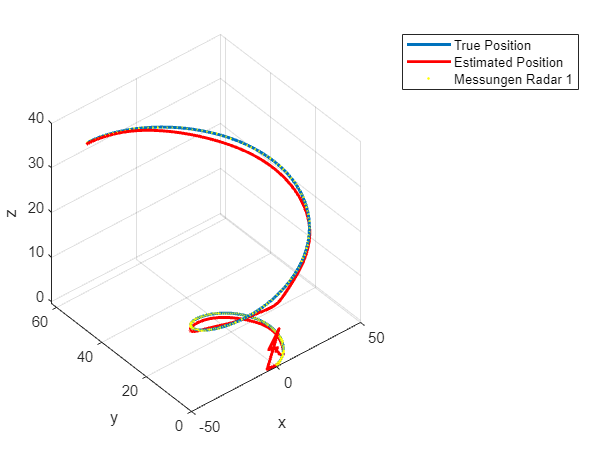

% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
plot3(messungen_kartesisch(1, :), messungen_kartesisch(2, :)-10, messungen_kartesisch(3, :), 'y.', 'MarkerSize', 5);
%plot3(messungen_kartesisch(4, :), messungen_kartesisch(5, :), messungen_kartesisch(6, :), 'r.', 'MarkerSize', 5);
hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position', 'Messungen Radar 1', 'Messungen Radar 2');

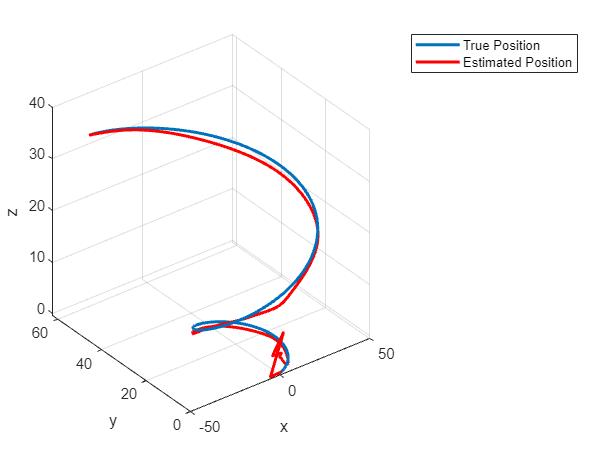



% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);

hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position');

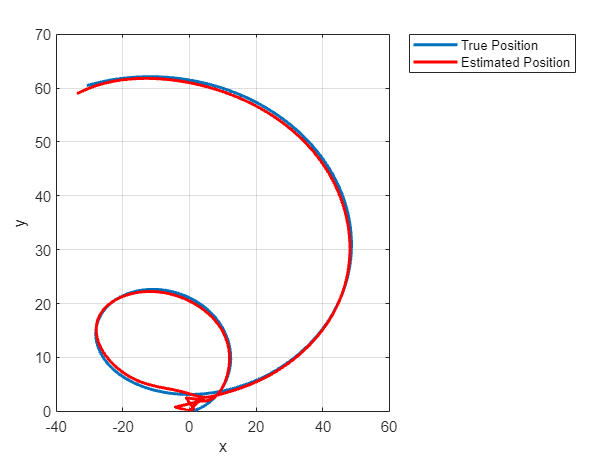


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(estimated_position(1, :), estimated_position(2, :), 'r', 'LineWidth', 2);

hold off;
xlabel('x');
ylabel('y');
grid on;
legend('True Position', 'Estimated Position');

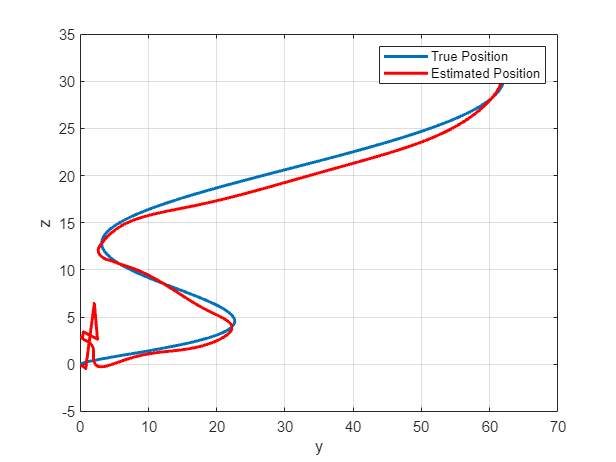



figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);

hold off;
xlabel('y');
ylabel('z');
grid on;
legend('True Position', 'Estimated Position');

function obs = calculate_observations(x_k, pos_radar)
    
    dist_matrix_radar1 = [];
    phi_radar1 = [];
    theta_radar1 = [];


    R_transposed = transpose(x_k);
    for i=1:length(R_transposed(:,1))
        dist_radar1 = norm(R_transposed(1:3) - pos_radar);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar
        dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1]; 
        % Berechnung des Elevationswinkels (phi) für Radar 1
        delta_z = R_transposed(3) - pos_radar(3);
        rho = sqrt((R_transposed(1) - pos_radar(1))^2 + (R_transposed(2) - pos_radar(2))^2 + delta_z^2);
        phi_radar1 = [phi_radar1;rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
        
        % Berechnung des Azimutwinkels (theta) für Radar 1
        delta_x = R_transposed(1) - pos_radar(1);
        delta_y = R_transposed(2) - pos_radar(2);
        theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    end 



    polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1];
    
    obs = transpose(polar_koordinaten_radar1);

end

function messungen = messungen_anpassen(x_k, pos_radar1, pos_radar2)

    x_k_new_arr = [];
    for i=1:length(x_k(1,:))
        x_k_new1 = x_k(1,i) - pos_radar1(1);
        x_k_new2 = x_k(1,i) - pos_radar1(2);
        x_k_new3 = x_k(1,i) - pos_radar1(3);
        x_k_new4 = x_k(1,i) - pos_radar2(1);
        x_k_new5 = x_k(1,i) - pos_radar2(2);
        x_k_new6 = x_k(1,i) - pos_radar2(3);
        x_k_new_arr = [x_k_new_arr; x_k_new1,x_k_new2,x_k_new3, x_k_new4,x_k_new5,x_k_new6];
    
    end
    messungen = transpose(x_k_new_arr);
end


function H = create_observation_matrix22(x_k, pos_radar1, pos_radar2)
    x = x_k;
    dx = x(1) - pos_radar1(1);
    dy = x(2) - pos_radar1(2);
    dz = x(3) - pos_radar1(3);
    d = sqrt(dx^2 + dy^2 + dz^2);
    dxy = sqrt(dx^2 + dy^2);

    H = zeros(6, 6);
    H(1,1) = dx / d;
    H(1,2) = dy / d;
    H(1,3) = dz / d;
    H(2,1) = -dy / dxy^2;
    H(2,2) = dx / dxy^2;
    H(3,1) = dx * dz / (d^2 * dxy);
    H(3,2) = dy * dz / (d^2 * dxy);
    H(3,3) = -dxy / d^2;

    dx = x(1) - pos_radar2(1);
    dy = x(2) - pos_radar2(2);
    dz = x(3) - pos_radar2(3);
    d = sqrt(dx^2 + dy^2 + dz^2);
    dxy = sqrt(dx^2 + dy^2);

    H(4,4) = dx / d;
    H(4,5) = dy / d;
    H(4,6) = dz / d;
    H(5,4) = -dy / dxy^2;
    H(5,5) = dx / dxy^2;
    H(6,4) = dx * dz / (d^2 * dxy);
    H(6,5) = dy * dz / (d^2 * dxy);
    H(6,6) = -dxy / d^2;
end

function H = create_observation_matrix(x_k, pos_radar1, pos_radar2)
    H = zeros(6, 6);
    H(1:3, 1:3) = eye(3);
    H(4:6, 4:6) = eye(3);

    obs_radar1 = calculate_observations(x_k, pos_radar1);
    obs_radar2 = calculate_observations(x_k, pos_radar2);

    % Beobachtung 1 (Abstand zu pos_radar1)
    dxyz = x_k(1:3, 1)' - pos_radar1;
    H(1, 1:3) = dxyz / obs_radar1(1);

    % Beobachtung 2 (Azimutwinkel zu pos_radar1)
    dxy = dxyz(1:2);
    H(2, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 3 (Elevationswinkel zu pos_radar1)
    H(3, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar1(3) * norm(dxyz)^3);

    % Beobachtung 4 (Abstand zu pos_radar2)
    dxyz = x_k(1:3, 1)' - pos_radar2;
    H(4, 1:3) = dxyz / obs_radar2(1);

    % Beobachtung 5 (Azimutwinkel zu pos_radar2)
    dxy = dxyz(1:2);
    H(5, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 6 (Elevationswinkel zu pos_radar2)
    H(6, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar2(3) * norm(dxyz)^3);
end


function kartesische_koordinaten_radar = get_kartesische_Koordianten(polar_koordinaten_radar)
    
    polar_koordinaten_radar = transpose(polar_koordinaten_radar);
    x_list1 = [];
    y_list1 = [];
    z_list1 = [];
    x_list2 = [];
    y_list2 = [];
    z_list2 = [];
    

    for i = 1:length(polar_koordinaten_radar(:,1))
        % Berechnung der kartesischen Koordinaten für Radar 1
        x_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* cos(deg2rad(polar_koordinaten_radar(i, 2)));
        y_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* sin(deg2rad(polar_koordinaten_radar(i, 2)));
        z_radar1 = polar_koordinaten_radar(i, 1) .* cos(deg2rad(polar_koordinaten_radar(i, 3)));
        x_list1 = [x_list1; x_radar1];
        y_list1 = [y_list1; y_radar1];
        z_list1 = [z_list1; z_radar1];

        
        % Berechnung der kartesischen Koordinaten für Radar 2
        x_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* cos(deg2rad(polar_koordinaten_radar(i, 5)));
        y_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* sin(deg2rad(polar_koordinaten_radar(i, 5)));
        z_radar2 = polar_koordinaten_radar(i, 4) .* cos(deg2rad(polar_koordinaten_radar(i, 6)));
        x_list2 = [x_list2; x_radar2];
        y_list2 = [y_list2; y_radar2];
        z_list2 = [z_list2; z_radar2];

    end
    % Kombinieren der kartesischen Koordinaten für Radar 1
    kartesische_koordinaten = [x_list1, y_list1, z_list1, x_list2, y_list2, z_list2]
    kartesische_koordinaten_radar = transpose(kartesische_koordinaten);


end